# Reduced order model for the soft robot

clearvars;
close all
clc

## Import data

load dataDecayObs
nTraj = size(oData,1);
rdof = 3;
odof = 3;
ndof = size(Xsnapshots,1)/2;

## Plot trajectories in an observable of interest

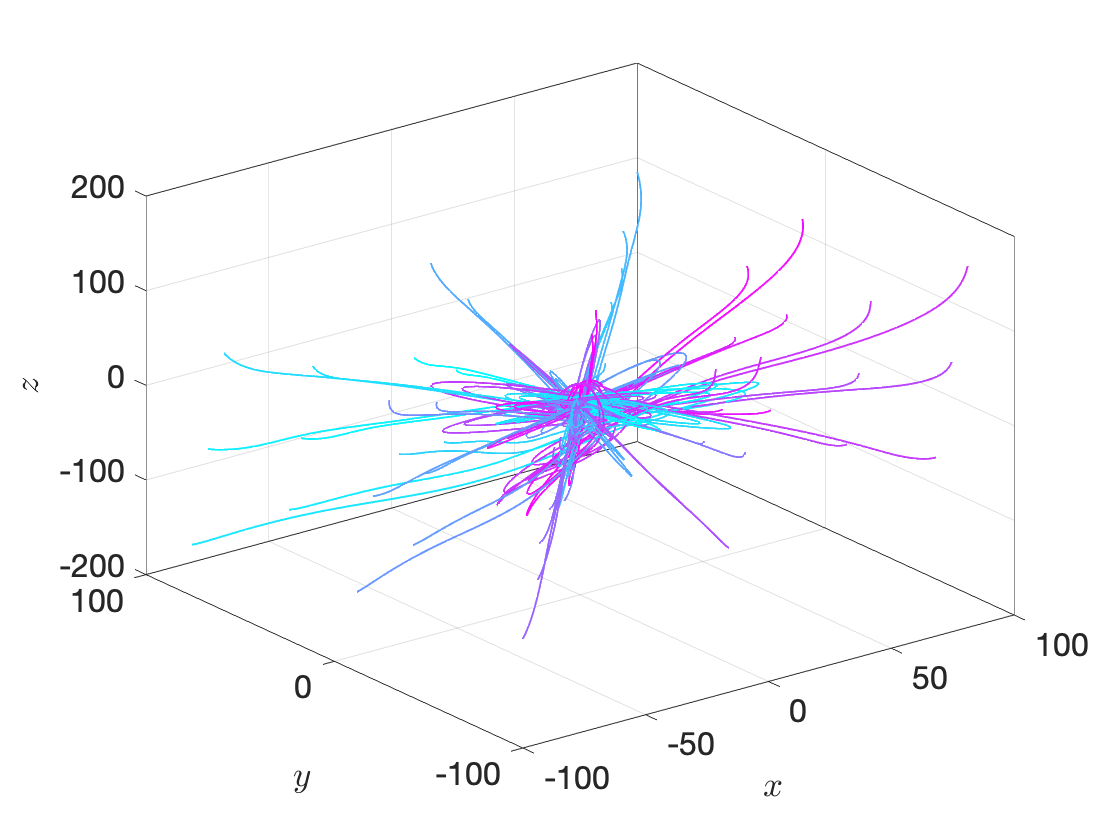

outdofs = [1 2 3];
customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(oData{iTraj,2}(outdofs(1),:),oData{iTraj,2}(outdofs(2),:),oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end
view(3)
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');

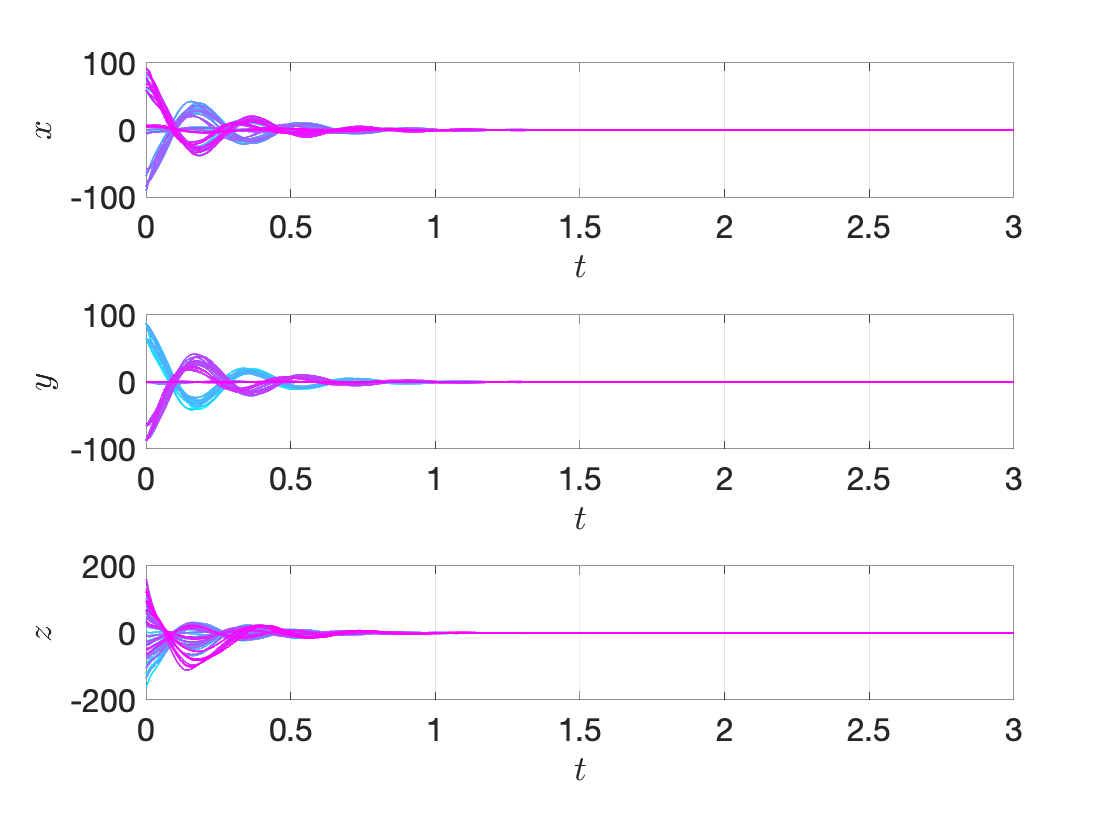


customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:nTraj
    subplot(311);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end

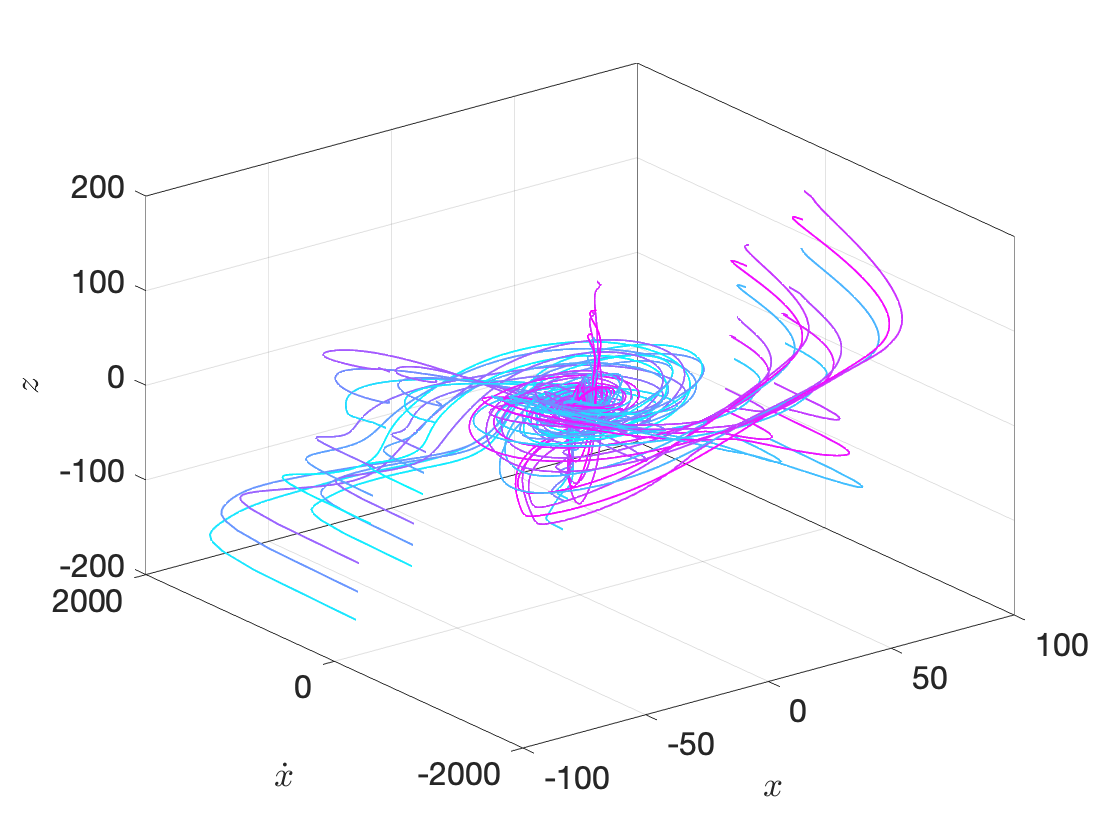


customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(oData{iTraj,2}(outdofs(1),:),oData{iTraj,2}(outdofs(1)+odof,:),oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end
view(3)
xlabel('$x$','Interpreter','latex');
ylabel('$\dot{x}$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');

## Show PCA infos

Modes were already computed to get yData

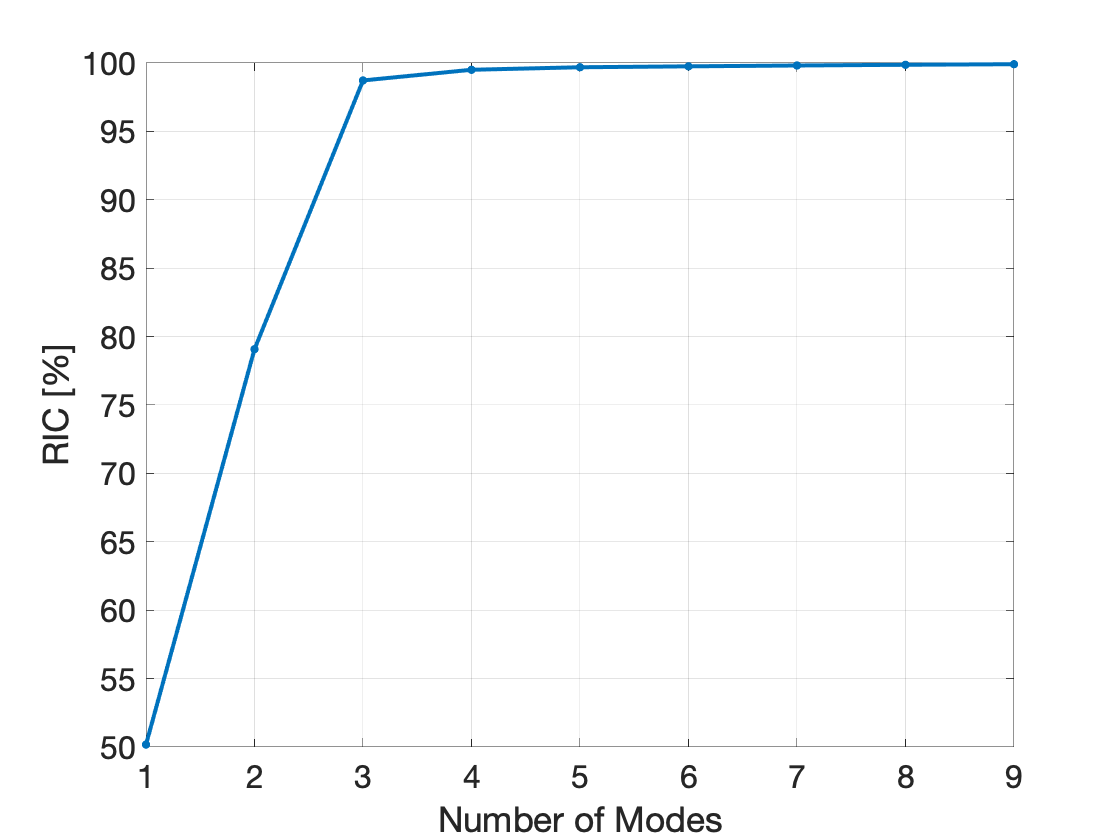

% Perform SVD on displacement field
[~,S,~] = svd(Xsnapshots(1:ndof,:),0);
% Plot variance description: we expect three modes to capture almost all
% variance. Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('RIC [%]');
xlim([1 9])
set(gca,'XTick',[1:1:9])

## Obtain reduced-order coordinates

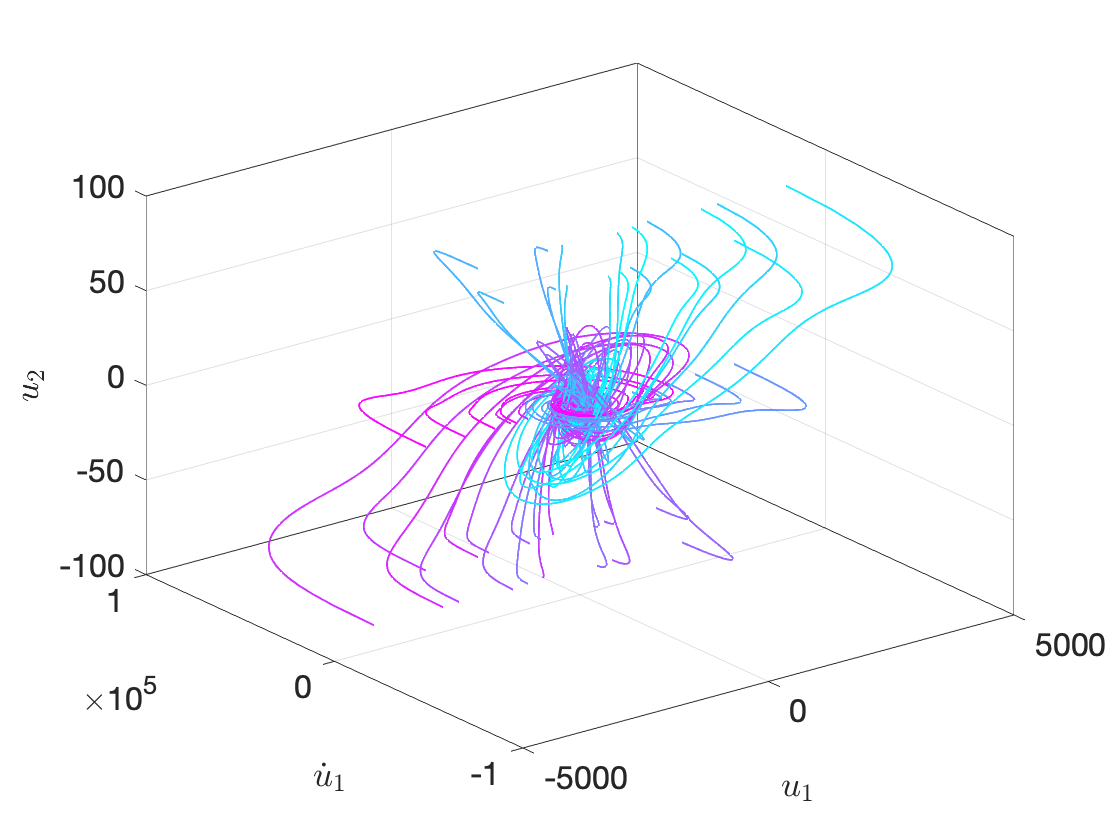

customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(yData{iTraj,2}(1,:),yData{iTraj,2}(1+rdof,:),oData{iTraj,2}(2,:),'Linewidth',1)
end
view(3)
xlabel('$u_1$','Interpreter','latex');
ylabel('$\dot{u}_1$','Interpreter','latex');
zlabel('$u_2$','Interpreter','latex');

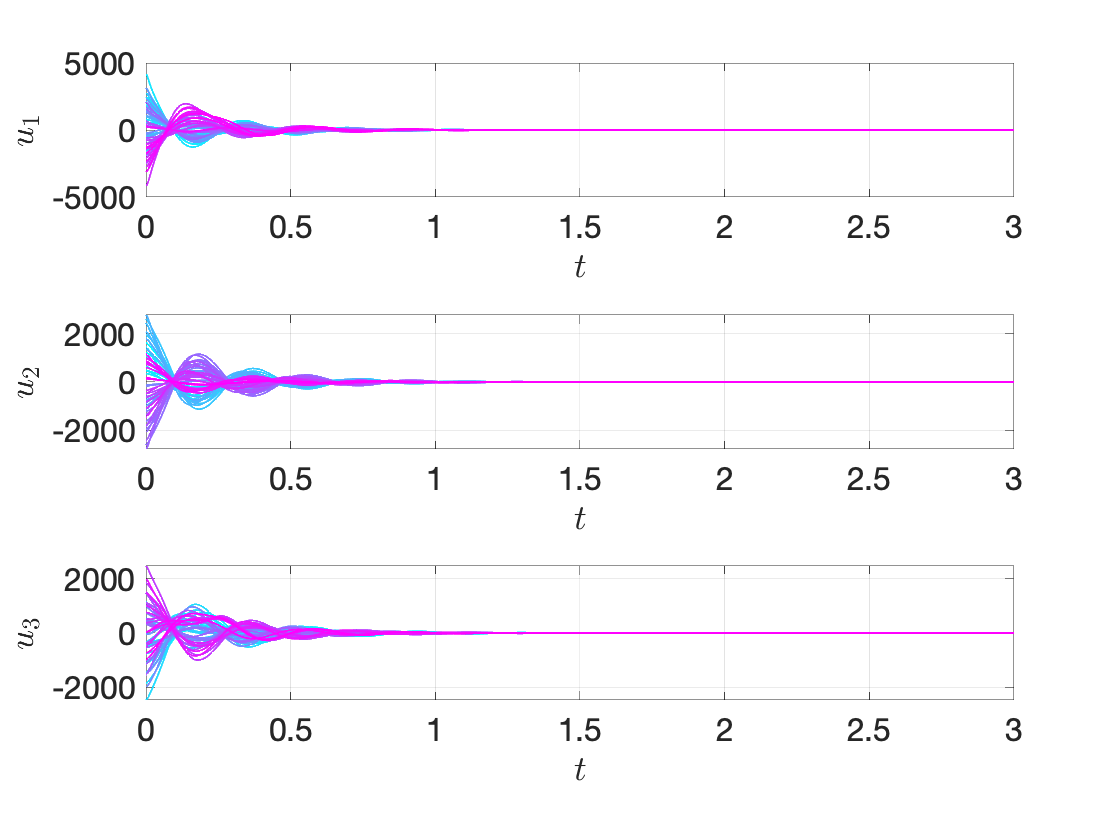


customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = 1:nTraj
    subplot(311);
    plot(yData{iTraj,1},yData{iTraj,2}(1,:),'Linewidth',1)
    subplot(312);
    plot(yData{iTraj,1},yData{iTraj,2}(2,:),'Linewidth',1)
    subplot(313);
    plot(yData{iTraj,1},yData{iTraj,2}(3,:),'Linewidth',1)
end

## Train and test data

indTest = [1 3 5 7 9 11 13 15];
indTrain = setdiff(1:nTraj,indTest);

## Truncate trajectories

sliceInt = [0.14 2.6];
oDataTrunc = sliceTrajectories(oData, sliceInt);
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Train Geometery of the SSM

SSMDim = 2*rdof;
SSMOrder = 3;
IMInfo = IMGeometry(oDataTrunc(indTrain,:),SSMDim, SSMOrder,'reducedCoordinates',yDataTrunc(indTrain,:));
IMInfoInv = IMGeometry(yDataTrunc(indTrain,:),SSMDim, SSMOrder,'reducedCoordinates',oDataTrunc(indTrain,:));

Evaluate parametrization error

% Compute and display error
% Train error
errorGeoTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yDataTrunc(indTrain(iTraj),:));
    errorGeoTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end
errorGeoTrain

errorGeoTrain =     0.1724    0.2347    0.2464    0.2612    0.1992    0.1530    0.2659    0.2498    0.1744    0.2904    0.1348    0.1771    0.2370    0.2221    0.1954    0.2306    0.1109    0.1999    0.1500    0.1900    0.0962    0.1156    0.1999    0.2354    0.2086    0.2338    0.1403    0.1736    0.1775    0.2786    0.1948    0.2418    0.4244    0.5136    0.3756    0.4997    0.1701    0.2166    0.2025    0.2622    0.2619    0.4220    0.2717    0.7078


meanErrorGeoTrain = mean(errorGeoTrain)

meanErrorGeoTrain = 0.2436

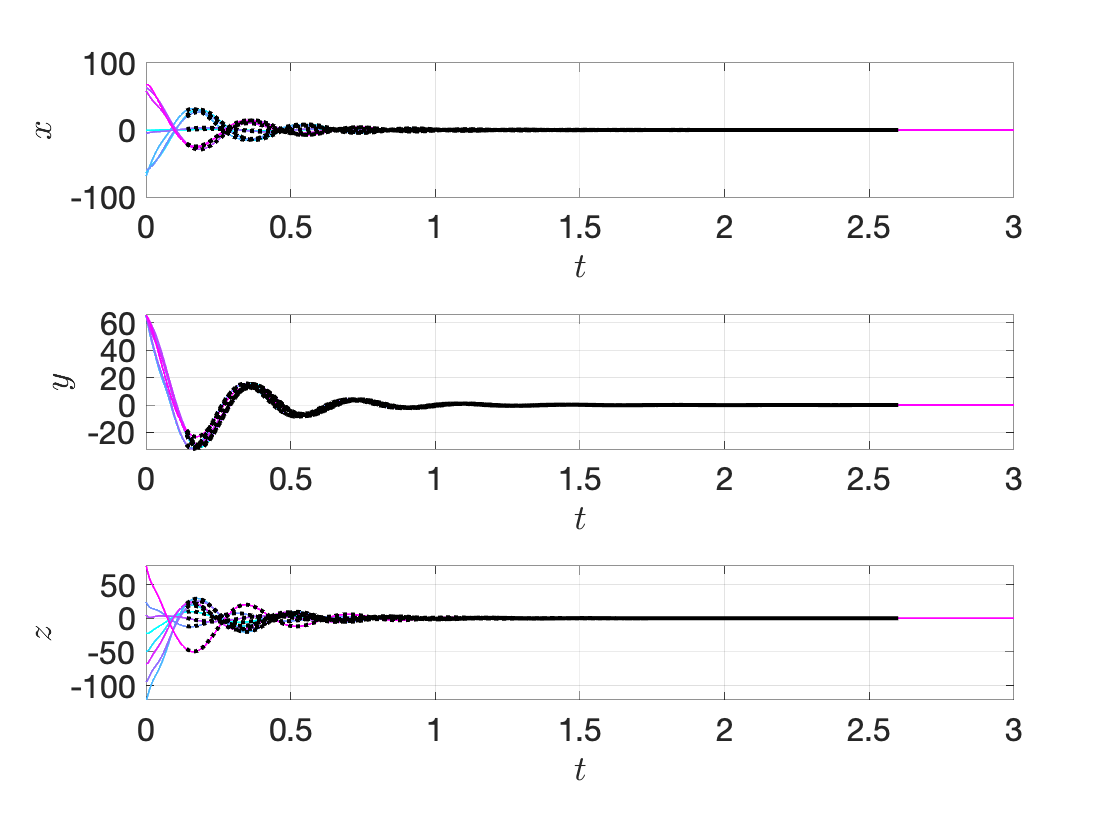

%
errorGeoTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    oRec = liftTrajectories(IMInfo, yDataTrunc(indTest(iTraj),:));
    errorGeoTest(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(oRec{1,1},oRec{1,2}(outdofs(1),:),'k:','Linewidth',2)
    subplot(312);
    plot(oRec{1,1},oRec{1,2}(outdofs(2),:),'k:','Linewidth',2)
    subplot(313);
    plot(oRec{1,1},oRec{1,2}(outdofs(3),:),'k:','Linewidth',2)
end

errorGeoTest

errorGeoTest =     0.1313    0.2045    0.2435    0.1947    0.1753    0.1162    0.2288    0.2548


meanErrorGeoTest = mean(errorGeoTest)

meanErrorGeoTest = 0.1936

Evaluate chart error

% Compute and display error
% Train error
errorGeoCTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    yRec = liftTrajectories(IMInfoInv, oDataTrunc(indTrain(iTraj),:));
    errorGeoCTrain(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTrain(iTraj),:))*100;
end
errorGeoCTrain

errorGeoCTrain =     0.1473    0.1958    0.1958    0.1955    0.1878    0.1188    0.2163    0.2214    0.1558    0.2222    0.1024    0.1522    0.1694    0.1627    0.1381    0.1935    0.1095    0.1753    0.1174    0.1485    0.0917    0.1132    0.1490    0.1897    0.1556    0.2226    0.0917    0.1255    0.1372    0.2272    0.1063    0.1245    0.3012    0.4449    0.2883    0.4486    0.1189    0.1676    0.1250    0.1647    0.2420    0.3972    0.2167    0.4970


meanErrorGeoCTrain = mean(errorGeoCTrain)

meanErrorGeoCTrain = 0.1925

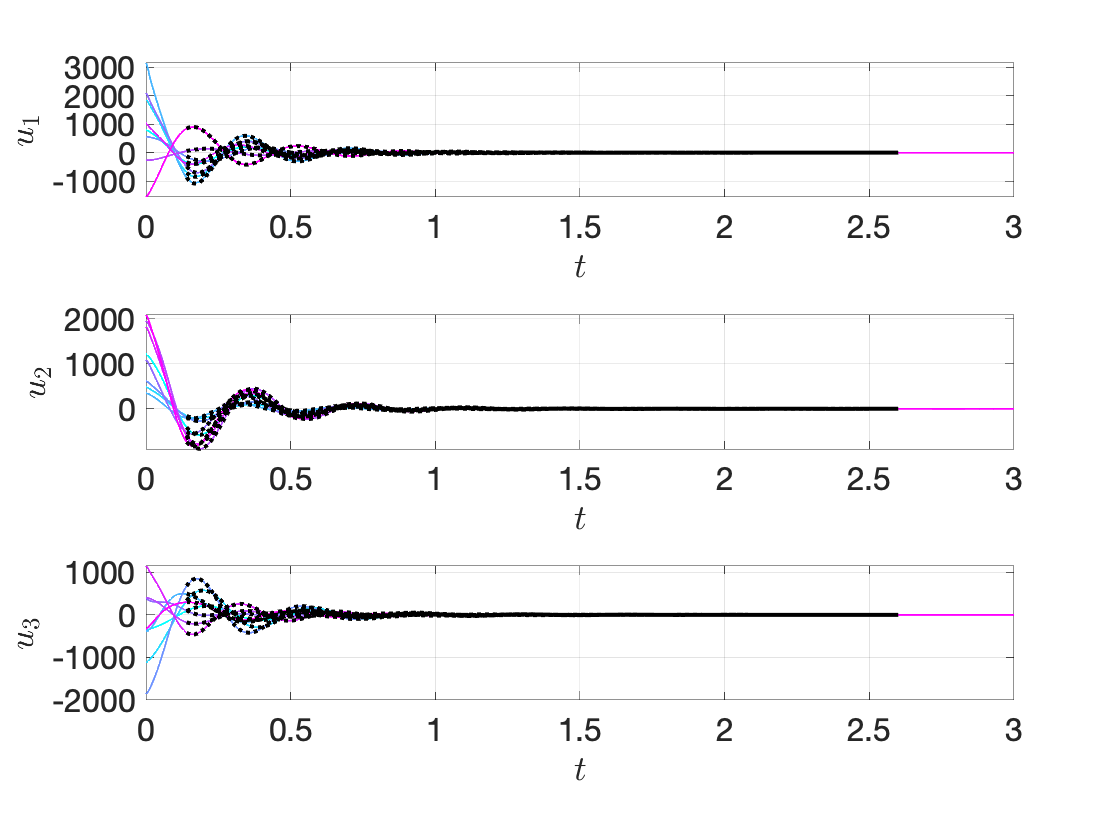

%
errorGeoCTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    yRec = liftTrajectories(IMInfoInv, oDataTrunc(indTest(iTraj),:));
    errorGeoCTest(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(yRec{1,1},yRec{1,2}(outdofs(1),:),'k:','Linewidth',2)
    subplot(312);
    plot(yRec{1,1},yRec{1,2}(outdofs(2),:),'k:','Linewidth',2)
    subplot(313);
    plot(yRec{1,1},yRec{1,2}(outdofs(3),:),'k:','Linewidth',2)
end

errorGeoCTest

errorGeoCTest =     0.1031    0.1550    0.1956    0.1329    0.1644    0.0938    0.1706    0.2135


meanErrorGeoCTest = mean(errorGeoCTest)

meanErrorGeoCTest = 0.1536

Store map in the same variables

sVar = {'map', 'polynomialOrder', 'dimension', 'nonlinearCoefficients', 'phi', 'exponents'};
for iVar = 1:length(sVar)
    IMInfo.chart.(sVar{iVar}) = IMInfoInv.parametrization.(sVar{iVar});
end

## Train Dynamics of the SSM (mechanical style - discrete dynamical system)

ROMOrder = 3;
RDInfo = IMDynamicsMap(yDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -3.4971 +16.7979i
  -3.5890 +17.1362i
  -3.6491 +18.3595i




yRec = advectRD(RDInfo, yDataTrunc);

normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 1.7863

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 0.7945

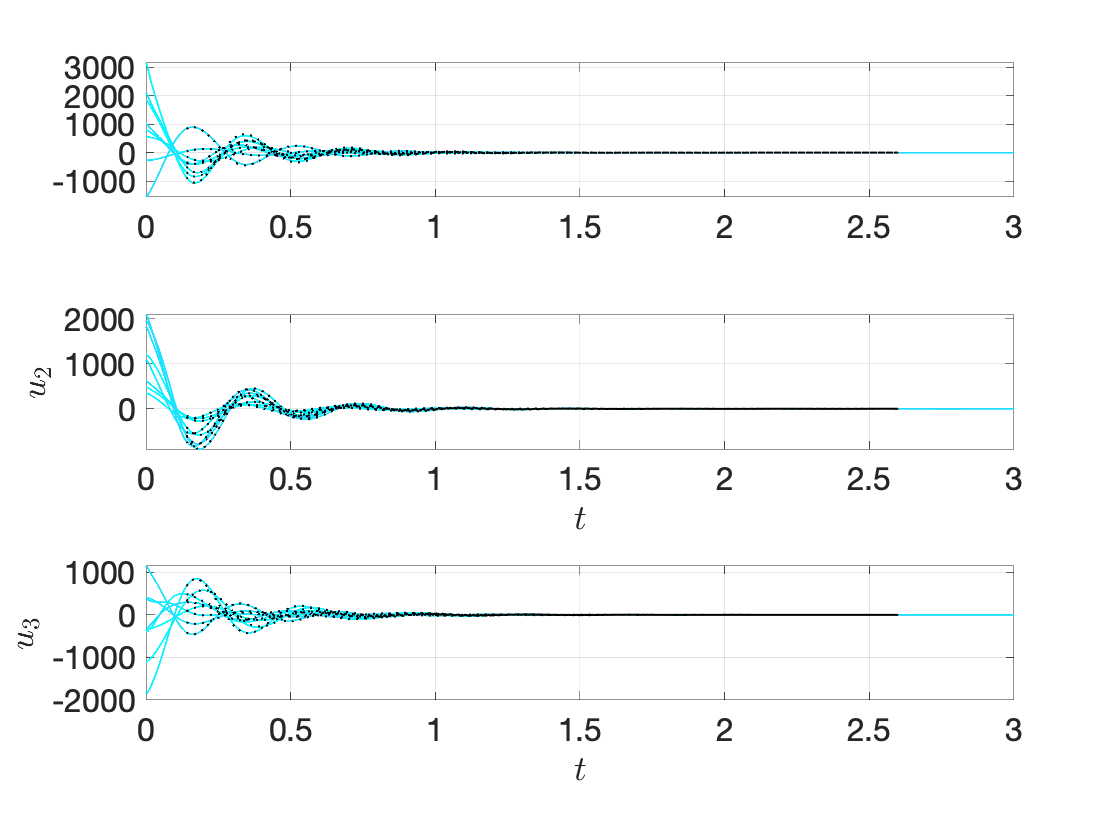


plotAll = 0;
if plotAll == 1
    vPlot = 1:nTraj;
else
    vPlot = indTest;
end
customFigure('subPlot',[3 1]);
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = vPlot
    subplot(311);
    plot(yData{iTraj,1},yData{iTraj,2}(1,:),'Linewidth',1)
    subplot(312);
    plot(yData{iTraj,1},yData{iTraj,2}(2,:),'Linewidth',1)
    subplot(313);
    plot(yData{iTraj,1},yData{iTraj,2}(3,:),'Linewidth',1)
end
for iTraj = vPlot
    subplot(311);
    plot(yRec{iTraj,1},yRec{iTraj,2}(1,:),'k:','Linewidth',1)
    subplot(312);
    plot(yRec{iTraj,1},yRec{iTraj,2}(2,:),'k:','Linewidth',1)
    subplot(313);
    plot(yRec{iTraj,1},yRec{iTraj,2}(3,:),'k:','Linewidth',1)
end

## Evaluate global error

% Train error
errorGloTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yRec(indTrain(iTraj),:));
    errorGloTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end
errorGloTrain

errorGloTrain =     0.6976    0.7036    0.6111    1.2715    1.1245    0.5800    1.3172    0.4094    0.6100    1.5501    0.4195    0.6018    0.8809    0.7506    0.6938    1.3131    0.4006    0.6692    1.0786    1.2039    0.3970    0.4422    0.4859    0.6682    0.4385    0.7910    0.4387    0.5835    0.8108    1.3173    0.4399    0.7984   11.3078    5.6251    6.3977    1.7606    0.7339    0.7762    0.4299    0.7917    4.5275    9.2505    2.0798    4.8859


meanErrorGloTrain = mean(errorGloTrain)

meanErrorGloTrain = 1.6606

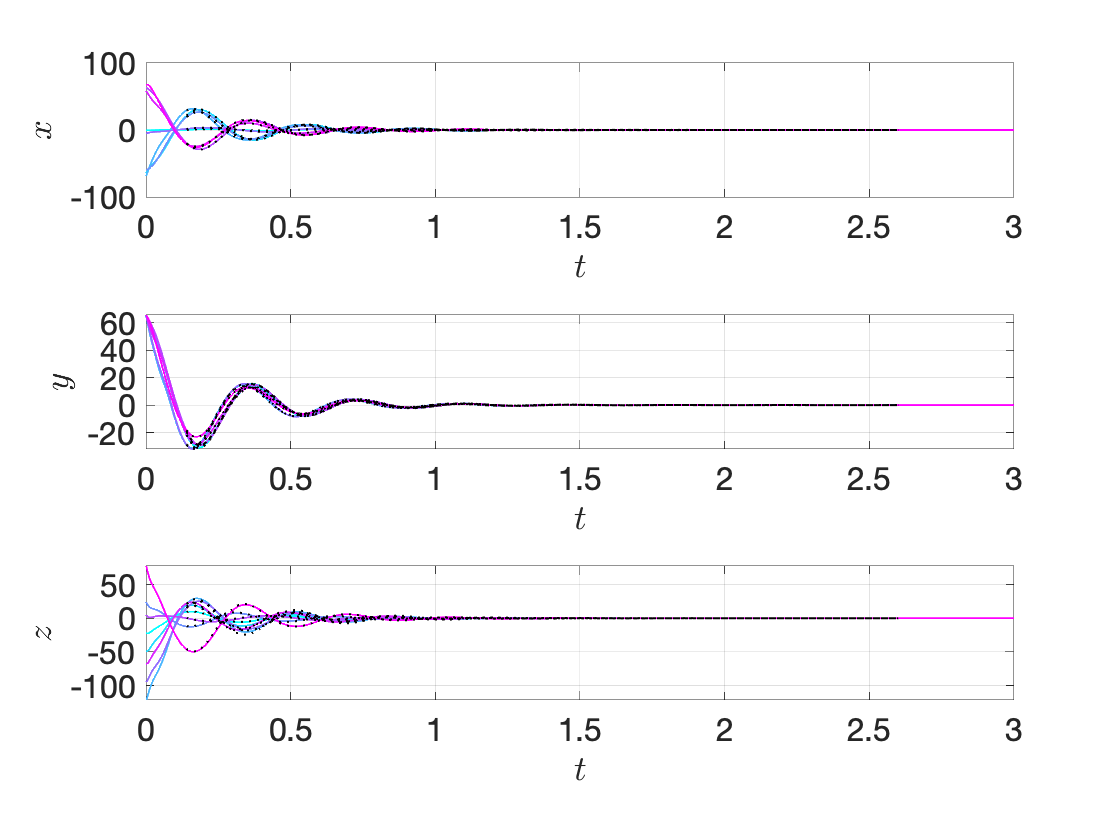

%
errorGeoTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    oRec = liftTrajectories(IMInfo, yRec(indTest(iTraj),:));
    errorGloTest(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(oRec{1,1},oRec{1,2}(outdofs(1),:),'k:','Linewidth',1)
    subplot(312);
    plot(oRec{1,1},oRec{1,2}(outdofs(2),:),'k:','Linewidth',1)
    subplot(313);
    plot(oRec{1,1},oRec{1,2}(outdofs(3),:),'k:','Linewidth',1)
end

errorGloTest

errorGloTest =     0.5316    0.9978    1.5589    0.9353    1.0137    0.3240    0.7069    0.6155


meanErrorGloTest = mean(errorGloTest)

meanErrorGloTest = 0.8355

## Understand which mode is more responsbile for what motion

outdofsMat = zeros(3,2*ndof);
output_node = 1354;
outdofsPS =  3*output_node + [1 2 3];

for ii = 1:3
outdofsMat(ii,outdofsPS(ii)) = 1;
end

redDynLinearPart = RDInfo.reducedDynamics.coefficients(:,1:2*rdof);
redStiffnessMat = -redDynLinearPart(rdof+1:end,1:rdof);
[UconsRedDyn,w2] = eig(redStiffnessMat);
[consFreqs,pos] = sort(sqrt(diag(w2))); UconsRedDyn = UconsRedDyn(:,pos);
[consFreqs abs(RDInfo.eigenvaluesLinPartFlow(1:3))];
Ucons = [UconsRedDyn zeros(rdof); zeros(rdof) UconsRedDyn];
Vcons = V*Ucons;
abs(RDInfo.eigenvaluesLinPartFlow(1:3))

ans =    17.1580
   17.5080
   18.7186


modesDir = outdofsMat*Vcons(:,1:rdof)

modesDir =     0.0381    0.0186   -0.0183
    0.0143   -0.0406   -0.0062
    0.0217    0.0050    0.0444


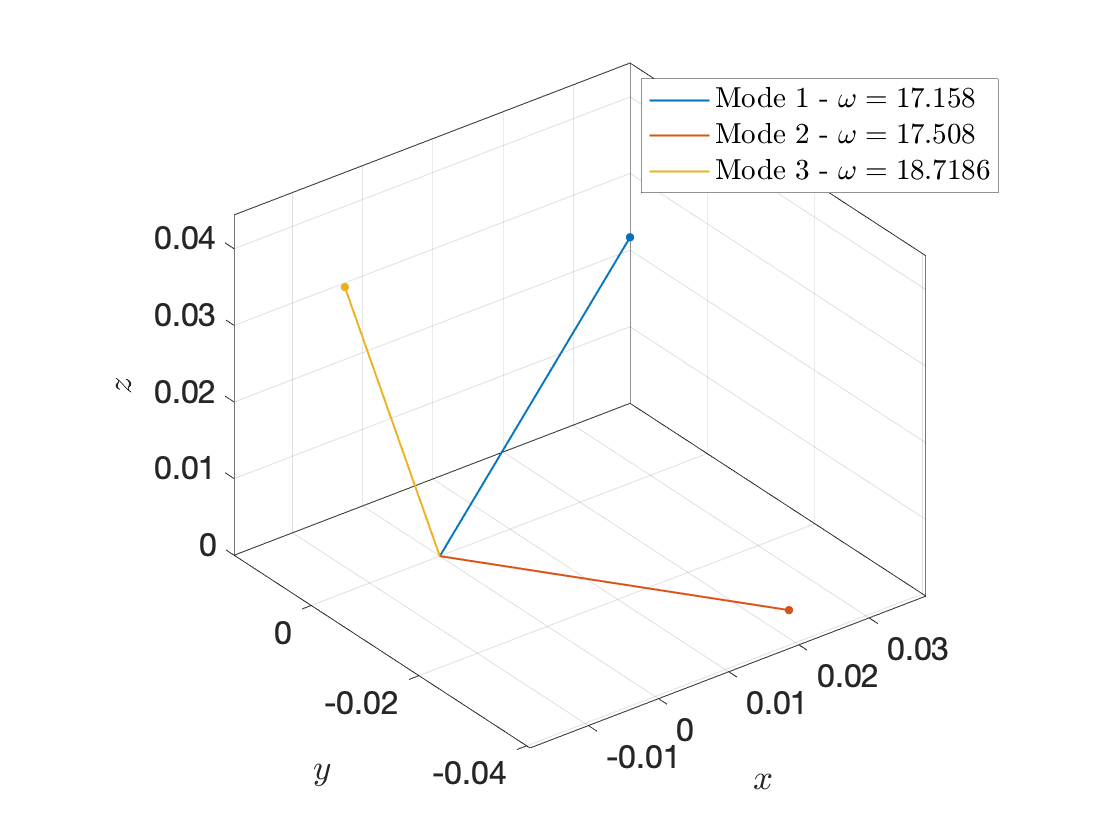

% Plots mode direction
customFigure; classicColors = colororder;
for ii = 1:3
plot3([0 modesDir(1,ii)],[0 modesDir(2,ii)],[0 modesDir(3,ii)],'Linewidth',1,'Color',classicColors(ii,:))
plot3([modesDir(1,ii)],[modesDir(2,ii)],[modesDir(3,ii)],'.','MarkerSize',12,'Color',classicColors(ii,:),'HandleVisibility','off')
end
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
legend(['Mode 1 - $\omega =  ' num2str(abs(RDInfo.eigenvaluesLinPartFlow(1))) '$'],...
    ['Mode 2 - $\omega =  ' num2str(abs(RDInfo.eigenvaluesLinPartFlow(2))) '$'],...
    ['Mode 3 - $\omega =  ' num2str(abs(RDInfo.eigenvaluesLinPartFlow(3))) '$'],'interpreter','latex')
view(3)
axis equal

% Hence mode 1 is mainly along x, mode 2 along y and mode 3 along z.

## Control


$$H_{\mathrm{red}} ={\mathrm{V}}^{\top } M^{-1} H$$


Hred = transpose(V(1:ndof,1:rdof))*(M\H);

normsModalForcing = mean((transpose(V(1:ndof,1:rdof))*(M\H)).^2,1)

normsModalForcing = 	1.0e+03 *

    3.6165    3.6851    2.7069    3.6295


normsNonModalForcing = mean(((eye(ndof)-V(1:ndof,1:rdof)*transpose(V(1:ndof,1:rdof)))*(M\H)).^2,1)

normsNonModalForcing = 	1.0e+03 *

    1.8746    1.5411    1.3337    1.2016


## Setup model for control

Accordin to the slides of June 2

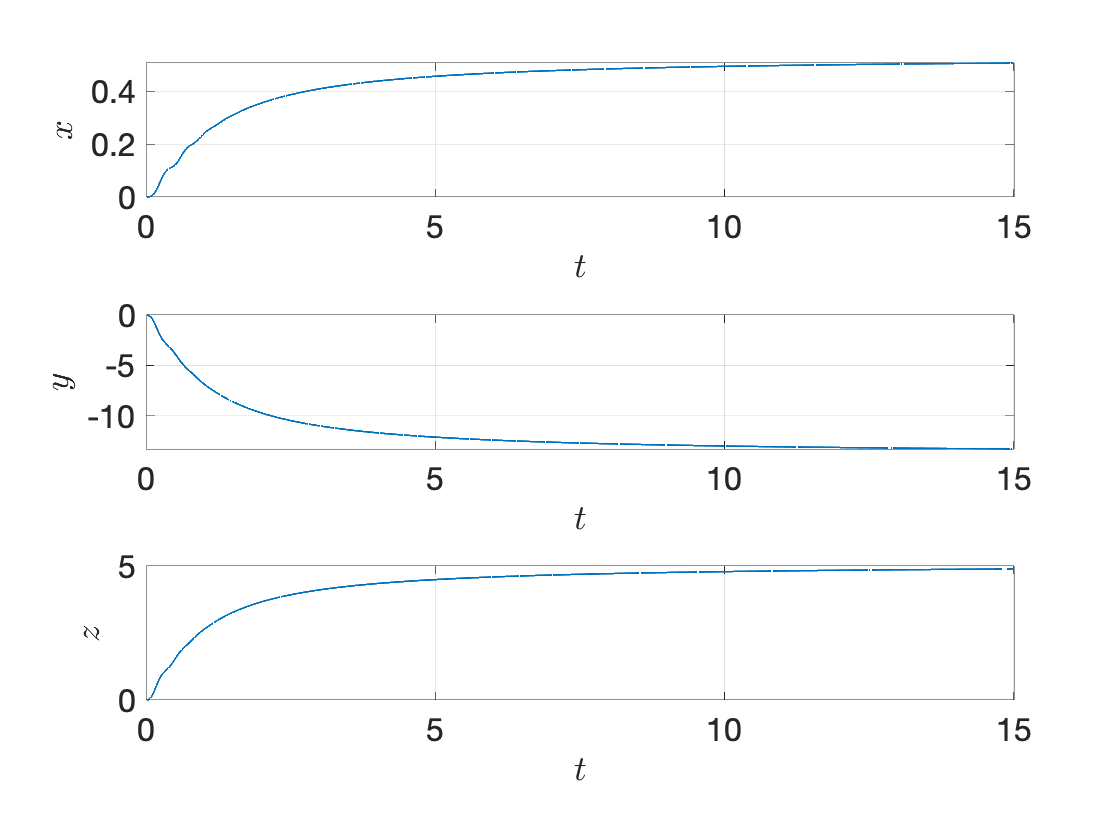

Rauton = RDInfo.reducedDynamics.map;
R = @(k,p,u) Rauton(p) + [zeros(rdof,size(Hred,2)); Hred]*u;
C = IMInfo.parametrization.map;
W = IMInfo.chart.map;

% Example
DeltaT = yData{1,1}(2)-yData{1,1}(1);
uFun = @(k) [atan(DeltaT*k)/pi*2; 0; 0; 0];
iters = 0:15000;
yTraj = iterateMapU(@(k,p) R(k,p,uFun(k)),length(iters),zeros(2*rdof,1));
oTraj = C(yTraj);
customFigure('subPlot',[3 1]); 
subplot(311); 
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); 
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313);
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
subplot(311);
plot(iters*DeltaT,oTraj(outdofs(1),:),'Linewidth',1)
xlim([iters(1) iters(end)]*DeltaT)
subplot(312);
plot(iters*DeltaT,oTraj(outdofs(2),:),'Linewidth',1)
xlim([iters(1) iters(end)]*DeltaT)
subplot(313);
plot(iters*DeltaT,oTraj(outdofs(3),:),'Linewidth',1)
xlim([iters(1) iters(end)]*DeltaT)